# ME 419 Hydraulic Lab 

**Names:** Julia Fay, Aiden Taylor 

**Date:** 2024.3.6

**Class:** ME419

**Description: **The purpose of this file is to simulate the hydraulic controller using a simulink model to compare to experimental results. 

## System Properties 

%Physical Properties 
Wm = 23; %lbs 

Wextra = 6; %lbs 

Wtot = Wm+Wextra; %lbf

m_ft = Wtot/32.174; %slugs (lbf*s^s/ft)

m = m_ft/12; %lbf*s^2/in mass of system. make sure units are in inches 

A = pi()*((0.5/2)^2-(0.25/2)^2);  %area of the piston surface 

%Gain Values 

Kp = 28;  %controller proportional gain 

Ka = 4.6; %amplifier gain. The input to the servo amp from the computer has a full-scale range of
          %±10 V. The output from the servo amp is in the range of ±50 mA.

Kq = 0.0125; %servo valve gain. controls flow of oil into the cylinder 

b = 0; %friction coefficient 

Kpot = 0.588; %potentiometer gain 

Kcmp = 1/0.588; %computer calculation gain because Kpot*Kcmp = 1

Kd = 0;

Ki = 0;

%Calculated Values

beta_Vt = 13305; %4*bulk modulus of the fluid/total volume of the fluid between the valve and piston 

Kce = 0.001; %reduction in flow due to backpressure 


## Block Diagram 

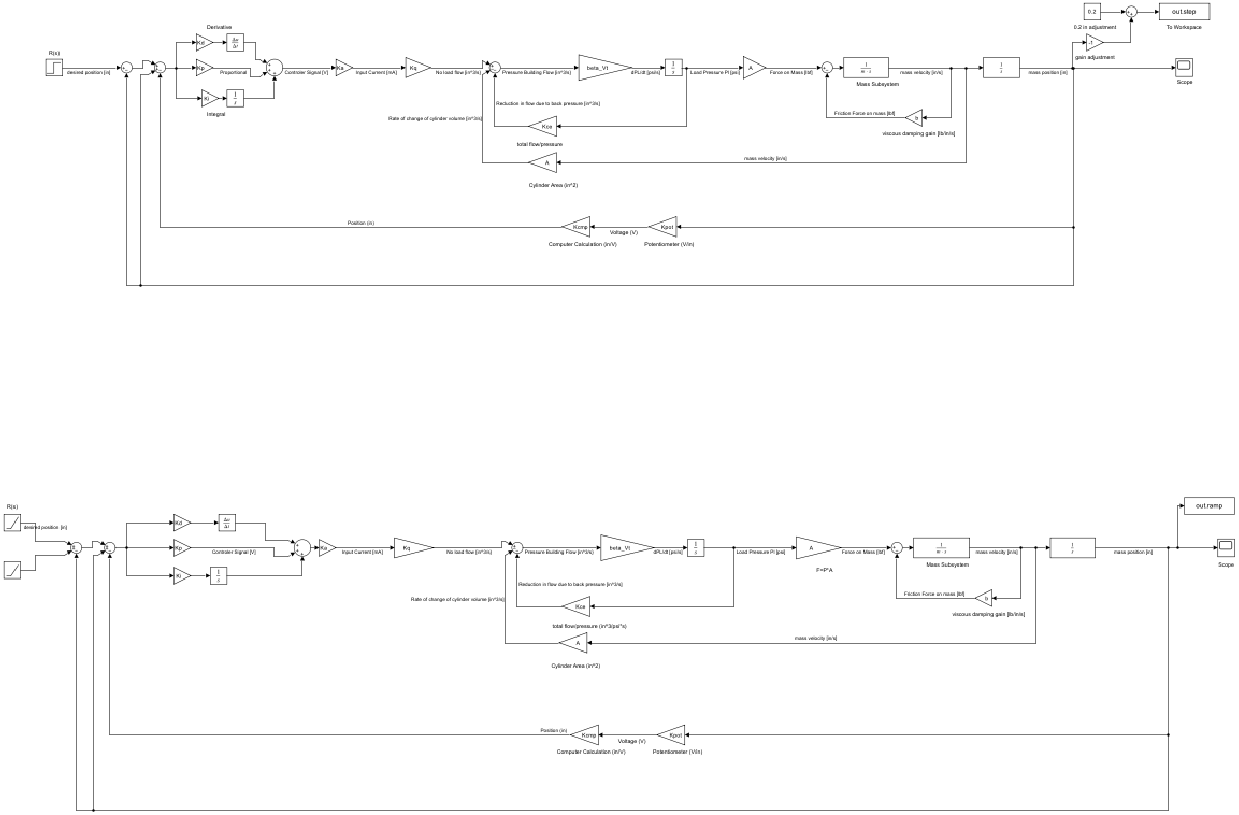

snapshotModel('Hydraulic_Lab_BD') %output simulink image

## Week 1 

%run simulation 
run1 = sim('Hydraulic_Lab_BD.slx');

%create a tiled layout 
fig1 = figure();
tl = tiledlayout(2,1);         
fig1.Position(3:4) = [560*3 420*5]; %scale subplot

%plot the results for case 1 and format
nexttile; 
plot(run1.tout,run1.step)
xlabel("Time [s]");
ylabel("Position [in]");
%axis([0 10 -0.1 0.6]);
title('Hydraulic System Model Response to Step Input','FontSize',10,'FontWeight','bold');
grid on

%plot the results for case 2 and format
nexttile; 
plot(run1.tout,run1.ramp)
xlabel("Time [s]");
ylabel("Position [in]");
%axis([0 10 -1 9]);
title('Hydraulic System Model Response to Ramp Input','FontSize',10,'FontWeight','bold');
grid on

## Week 2 

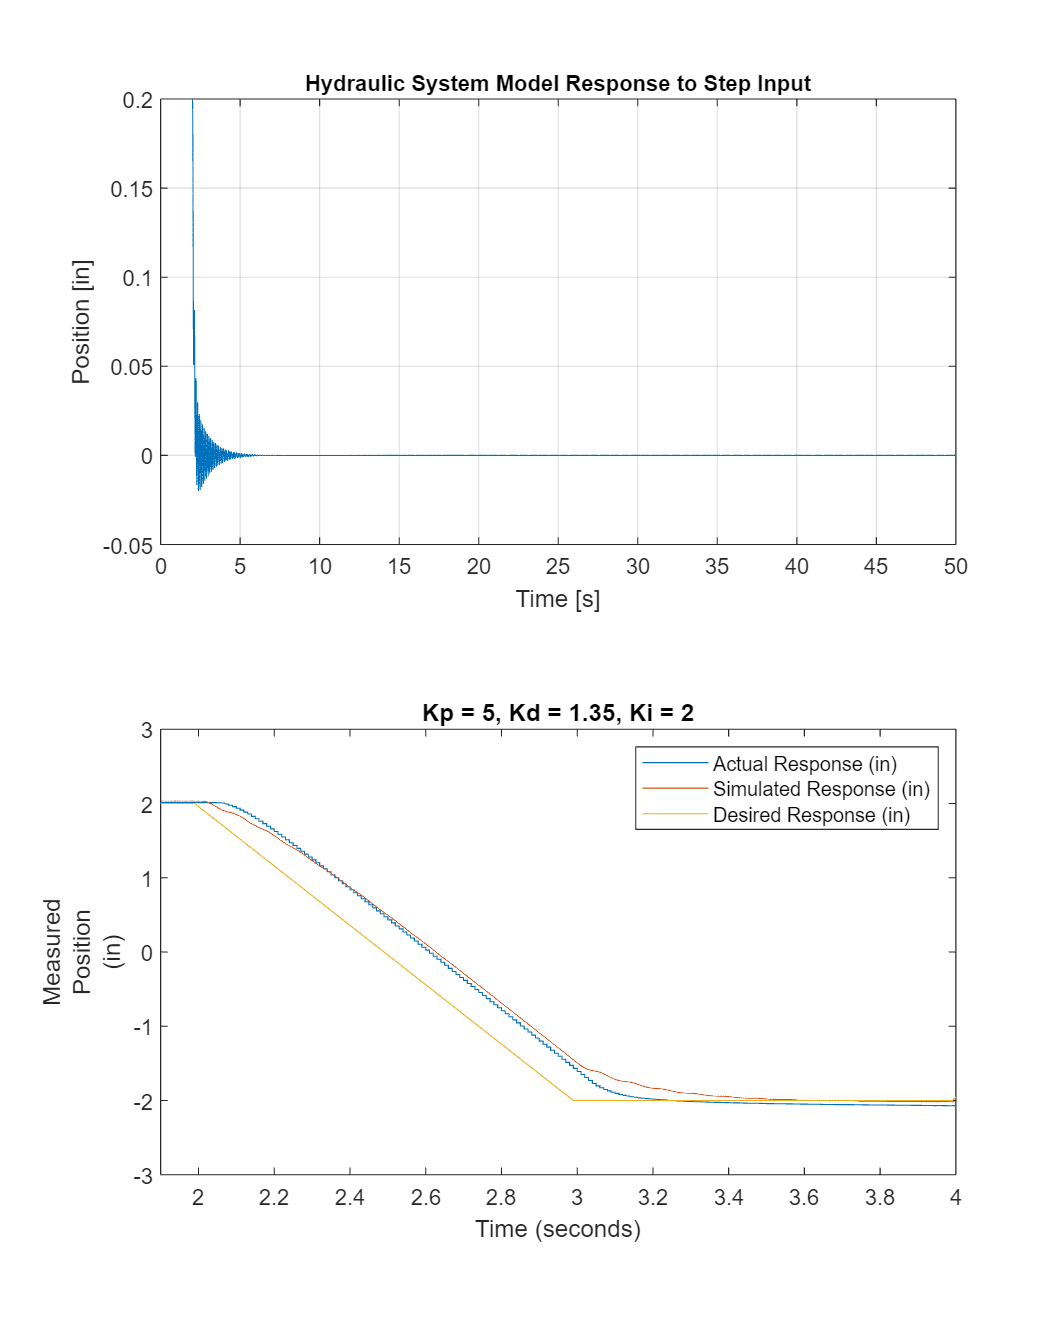

%Plotting part 2a from week 2
Kp = 12;
Kd = 1.35;
Ki = 0;
run1 = sim('Hydraulic_Lab_BD.slx');
data2a = load('P5D1.35week2a.mat');
data2a = data2a.data(1);
response = data2a{4}.Values;
plot(response)
hold on
plot(run1.tout, run1.step)
plot(data2a{2}.Values)
xlim([1.5 3.5])
legend('Actual Response (in)', 'Simulated Response (in)', 'Desired Response (in)')
title('Kp = 5, Kd = 1.35, Ki = 0')
hold off


%Plotting part 2b from week 2
Kp = 12;
Kd = 0;
Ki = 2;
run1 = sim('Hydraulic_Lab_BD.slx');
data2b = load('P5I2week2b.mat');
data2b = data2b.data(1);
response = data2b{4}.Values;
plot(response)
hold on
plot(run1.tout, run1.ramp)
plot(data2b{2}.Values)
xlim([1.9 4])
legend('Actual Response (in)', 'Simulated Response (in)', 'Desired Response (in)')
title('Kp = 5, Kd = 0, Ki = 2')
hold off

%Plotting part 2c from week 2
Kp = 20;
Kd = 1.35;
Ki = 2;
run1 = sim('Hydraulic_Lab_BD.slx');
data2c = load('P5I2D1.35week2c.mat');
data2c = data2c.data(1);
response = data2c{4}.Values;
plot(response(:,1))
hold on
plot(run1.tout, run1.ramp)
plot(data2c{2}.Values)
xlim([1.9 4])
legend('Actual Response (in)', 'Simulated Response (in)', 'Desired Response (in)')
title('Kp = 5, Kd = 1.35, Ki = 2')
hold off